clear all;close all;

% mo=load('C:\Users\sgrc-325\Desktop\git\pipes\data\1014_0.CSV');  %cigu 0.7m 12v runtest
% mo=load('C:\Users\sgrc-325\Desktop\git\pipes\data\1029_8.CSV');  %DOHZ 2~10hz 0.7m 12v 24v
% mo=load('C:\Users\sgrc-325\Desktop\git\pipes\data\1030_0.CSV');  %DOHZ h1 test
% mo=load('C:\Users\sgrc-325\Desktop\git\pipes\data\1030_1.CSV');  %DOHZ 3、4hz 0.7m 6v 12v 24v
% mo=load('C:\Users\sgrc-325\Desktop\git\pipes\data\1101_1.CSV');  %DOHZ car run 4hz*2 0.7m 12v 24v
% mo=load('C:\Users\sgrc-325\Desktop\git\pipes\data\1105_1.CSV');  %DOHZ 4hz*2 0.7m dictionary、run
% mo=load('C:\Users\sgrc-325\Desktop\git\pipes\data\1106_1.CSV');  %DOHZ fix time for fu
% mo=load('C:\Users\sgrc-325\Desktop\git\pipes\data\1108_1.CSV');  %DOHZ 4hz*2 0.7m iron pipe test run
% mo=load('C:\Users\sgrc-325\Desktop\git\pipes\data\1112_6.CSV'); %DOHZ 4hz*2 0.7m high 2m test run
% mo=load(['C:\Users\sgrc-325\Desktop\git\pipes\data\1112_7.CSV']); %DOHZ 4hz*2 0.7m high 2m iron pipe test run
% mo=load(['C:\Users\sgrc-325\Desktop\git\pipes\data\1113_1.CSV']); %DOHZ 4hz*2 0.7m high 2m blank、60、80cm/s iron pipe test run
% mo=load(['C:\Users\sgrc-325\Desktop\git\pipes\data\1114_0.CSV']); %DOHZ 4hz*2 0.7m high 2m、2mside blank、40、70、90cm/s iron pipe test run
% mo=load(['C:\Users\sgrc-325\Desktop\git\pipes\data\1127_1.CSV']); %DOHZ 4hz*2 0.7m high 2m、2mside 70cm/s iron pipe test run
mo=load(['C:\Users\sgrc-325\Desktop\git\gps\data\1210_38.CSV']); %DOHZ 4hz*2 0.7m high 2m、2mside 70cm/s iron pipe test run

% mo=mo(389000:392000,:);

moo=mo;
mo=moo(:,[1:17]);
% mo(1,:)=[];

[No,~]=size(moo);
t0=[1 No];
t=moo(:,1);
[a1 a3]=size(moo);
[a1 a2]=size(mo);
f=moo(:,a3); %freqency
mo_cor=zeros(a1,a2);
% mo_cor=mo;

% mo(a1-200:a1,:)=[];
t=mo(:,1);

% mo_cor(:,1)=mo(:,1);
% for i=1:a1   %校正數據
%     mo_cor(i,2:4)=(Ta*Ka*(mo(i,2:4)'+Ba))';
%     mo_cor(i,5:7)=(Tg*Kg*(mo(i,5:7)'+Bg))';
%     mo_cor(i,8:10)=(Tm2a*(mo(i,8:10)'+Bm))';
%     mo_cor(i,11:13)=(Tm2a_2*(mo(i,11:13)'+Bm_2))';
% end

% acc1 = mo_cor(:,2:4);  %有校正
% gyr=mo_cor(:,5:7);
% % acc2 = mo_cor(:,5:7);
% m = mo_cor(:,8:10)*0.01;   %%%% to guess
% m2 = mo_cor(:,11:13)*0.01;   %%%%

acc1 = mo(:,3:5);  %無校正
acc2 = mo(:,6:8);  %無校正
gyr1=mo(:,9:11);
gyr2=mo(:,12:14);
m = mo(:,15:17); %%%% to guess
temp=moo(:,20:23);
h1=moo(:,18);
h2=moo(:,19);
magt=moo(:,20);
imu1t=moo(:,21);
imu2t=moo(:,22);
mcut=moo(:,23);
f=moo(:,24);
delay=moo(:,25);
ax1=acc1(:,1);ay1=acc1(:,2);az1=acc1(:,3);
ax2=acc2(:,1);ay2=acc2(:,2);az2=acc2(:,3);
aGo=sqrt(mo_cor(:,2).^2+mo_cor(:,3).^2+mo_cor(:,4).^2);
aG=sqrt(ax1.^2+ay1.^2+az1.^2);
aG2=sqrt(ax2.^2+ay2.^2+az2.^2);
GG=sqrt(gyr1(:,1).^2+gyr1(:,2).^2+gyr1(:,3).^2)*0.01;
GG2=sqrt(gyr2(:,1).^2+gyr2(:,2).^2+gyr2(:,3).^2)*0.01;
mm4=sqrt(m(:,1).^2+m(:,2).^2+m(:,3).^2);
% mm42=sqrt(m2(:,1).^2+m2(:,2).^2+m2(:,3).^2);
stdd=std(mo)'; %看標準差
stdd_cor=std(mo_cor)';

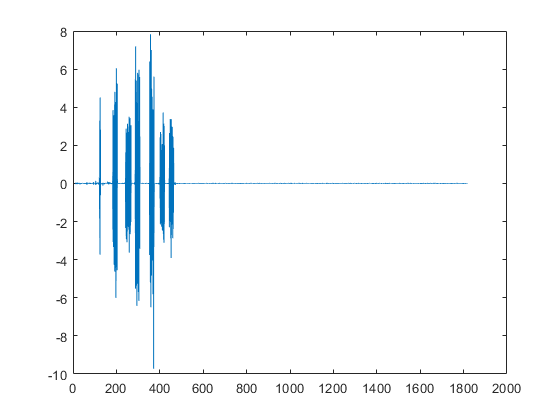

close all
% figure(1)
% subplot(2,1,1)
% plot(t,smooth(GG,200))
% subplot(2,1,2)
% plot(t,smooth(GG2,200))
% 
% figure(2)
% plot(t,mm4)

figure(2)
plot(t,ax1)

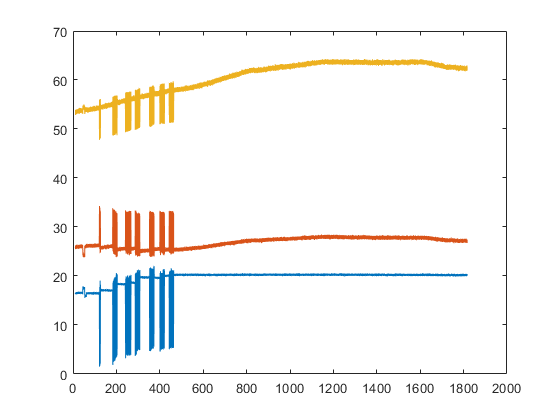


figure(3)
plot(t,m)

% hold on
% plot(t,m(:,1)+500)
% plot(t,m(:,2)-100)
% plot(t,m(:,3)-500)
% hold off

% figure(4)
% % plot(t,m(:,1))
% % plot(t,m(:,2))
% plot(t,m(:,3))

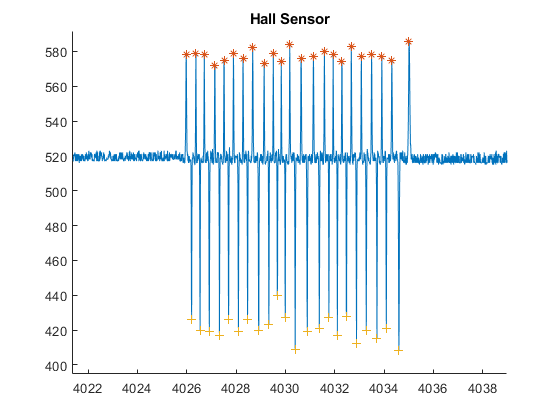

close all
addpath('C:\Users\sgrc-325\Desktop\git\matlabs');
h2t=[t h2];

% et=1810;ete=et+30;  %1127_1.csv blank
et=1895;ete=et+30;  %1127_1.csv blank



[~,et]=min(abs(t-et));
[~,ete]=min(abs(t-ete));

% h2t=[t(et:ete) h2(et:ete)];

Eth = 100; % Threshold for peak detection
cir = 0.29045;   % Wheel circumference in meters
[DfromH,VfromH,AfromH,AV] = Encoder_3f(h2t,Eth,cir);


fprintf('end position : %.5f m\n', DfromH(end));

end position : 117.04355 m


fprintf('average velocity : %.5f m/s\n', mean(AV));

average velocity : 0.04537 m/s


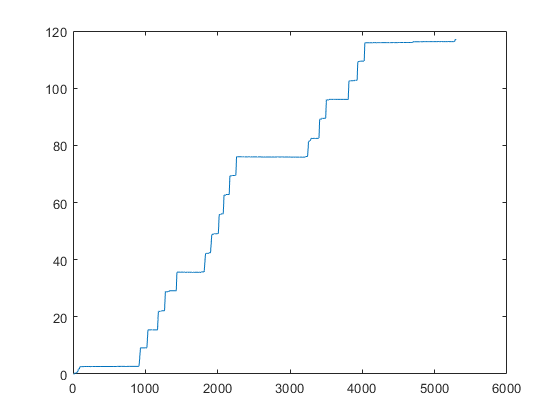


% figure(2)
% plot(t(et:ete),DfromH)
% figure(3)
% plot(t(et:ete),VfromH)

figure(2)
plot(t,DfromH)

% figure(3)
% plot(tt1,VfromH)

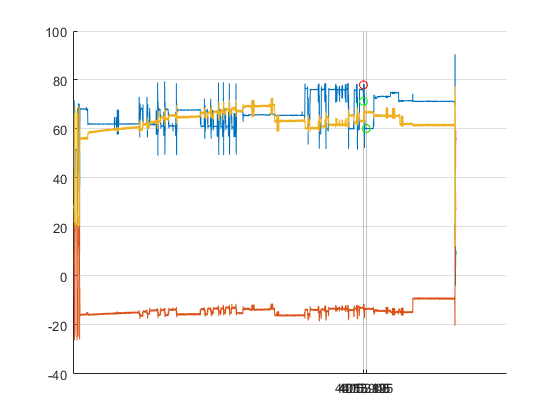

close all

long=25*6; %peak 數 
% tt1=1158.96; %開始時間 1127_1 1-1
% tt1=1254.16;tt2=tt1+0.13; %開始時間 1127_1 1-2
% tt1=1419.56; %開始時間 1127_1 1-3
% tt1=1992.935; %開始時間 1127_1 1-4
% tt1=2067.855; %開始時間 1127_1 1-5
% tt1=2149.49; %開始時間 1127_1 1-6
% tt1=2243.895; %開始時間 1127_1 1-7
% tt1=2471.09;long=25*4; %開始時間 1127_1 dic 1-1
% tt1=2736.258;long=25*4; %開始時間 1127_1 dic 1-2
% tt1=2817.585;long=25*4; %開始時間 1127_1 dic 1-3
% tt1=3390.33; %開始時間 1127_1 2-1
% tt1=3485.06;tt2=tt1+0.1; %開始時間 1127_1 2-2
% tt1=3797.57; %開始時間 1127_1 2-3
% tt1=3917.59; %開始時間 1127_1 2-4
tt1=4015.83; %開始時間 1127_1 2-5
% tt1=4327.48;tt2=tt1+0.13; %開始時間 1127_1 dic 2-1
% tt1=4415.645;tt2=tt1+0.13; %開始時間 1127_1 dic 2-2
% tt1=4537.885;tt2=tt1+0.135; %開始時間 1127_1 dic 2-3


tt2=tt1+0.115;
hz=4;
tn=tt1+long;
ticks=[];ticks2=[];
ticks(1:long)=0;
for i=1:long
    ticks(i)=tt1+(i-1)*(1/hz);
    ticks2(i)=tt2+(i-1)*(1/hz);
end
tickss=ticks;
tickss2=ticks2;
for i=1:long
    [~,tickss(i)]=min(abs(t-ticks(i))); %find the position of the time
    [~,tickss2(i)]=min(abs(t-ticks2(i))); %find the position of the time
end
paxis=1;

figure(1)
hold on
plot(t,m)
plot(ticks(1),m(tickss(1),paxis),'ro')
plot(ticks2(1),m(tickss2(1),paxis),'go')
plot(ticks(end),m(tickss(end),paxis),'ro')
plot(ticks2(end),m(tickss2(end),paxis),'go')
hold off
tag=[ticks(1) ticks2(1) ticks(end) ticks2(end)];
set(gca, 'xtick', tag);
grid on

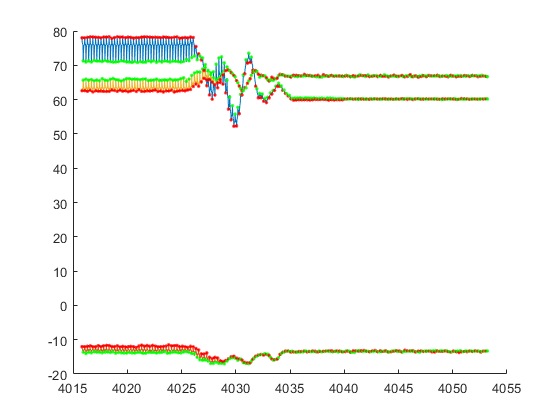


figure(2)
hold on
% plot(t,m)
plot(t(tickss(1):tickss(end)),m(tickss(1):tickss(end),:))
for i=1:long
    plot(ticks(i),m(tickss(i),1),'r.')
    plot(ticks(i),m(tickss(i),2),'r.')
    plot(ticks(i),m(tickss(i),3),'r.')
    plot(ticks2(i),m(tickss2(i),1),'g.')
    plot(ticks2(i),m(tickss2(i),2),'g.')
    plot(ticks2(i),m(tickss2(i),3),'g.')
end
hold off



% got m from peak and back
gotb1=[];gotb2=[];gotm1=[];gotm2=[];e1=[];e2=[];em=[];
gotb1(long,3)=zeros;
gotb2(long,3)=zeros;
gotm1(long,3)=zeros;
gotm2(long,3)=zeros;
e1(long,1)=zeros;
e2(long,1)=zeros;

fk=-4;
bk=8;

for i=1:long %算出背景值
    gotb1(i,:)=(m(tickss(i)+fk,:)+m(tickss(i)+bk,:))/2;
    gotb2(i,:)=(m(tickss2(i)+fk,:)+m(tickss2(i)+bk,:))/2;
end
for i=1:long %算出扣完背景值後的磁力
    gotm1(i,:)=m(tickss(i),:)-gotb1(i,:);
    gotm2(i,:)=m(tickss2(i),:)-gotb2(i,:);
end

for i=1:long
    e1(i)=DfromH(tickss(i));
    e2(i)=DfromH(tickss2(i));
end
e1=e1-e1(1);
e2=e2-e2(1);
e1(end)

ans = 6.4497

e2(end)

ans = 6.4506

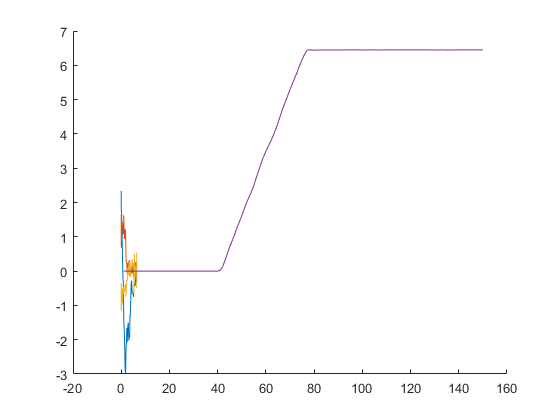


figure(5)

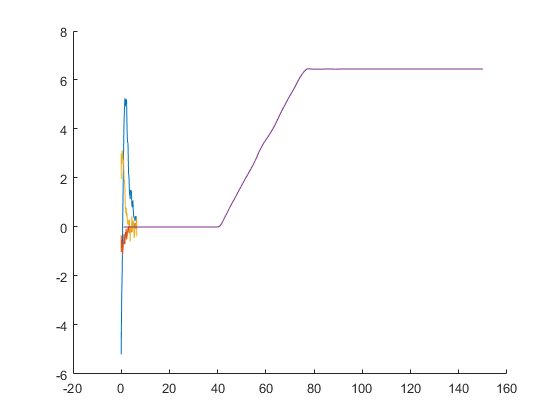

plot(e1,gotm1)
figure(6)
plot(e2,gotm2)


em=[e1 gotm1 e2 gotm2];

close all

h2tt=[t(tickss(1):tickss(end)) h2(tickss(1):tickss(end))];
[DDfromH,VVfromH,AAfromH,AAV] = Encoder_3f(h2tt,Eth,cir);
fprintf('end position : %.5f m\n', DDfromH(end));
fprintf('average velocity : %.5f m/s\n', mean(AAV));

% resample for encoder and mag
close all;

reb=load("reblank241114.mat"); % function form
reb=reb.reblank241114;
% reb=load("reblank241114002.mat"); % function form
% reb=reb.reblank241114002;

h2t=[t h2];

Eth = 90; % Threshold for peak detection
cir = 0.29045;   % Wheel circumference in meters
[DfromH,VfromH,AfromH,AV] = Encoder_3f(h2t,Eth,cir);

figure(1)
plot(t,DfromH)

% resample for encoder and mag

% rs=407.636; % 1113_1.csv_blank
% re=455.179;

% rs=1131.8; % 1113_1.csv_1
% re=1145.92;

% rs=1461.5; % 1113_1.csv_2
% re=1471.96;

% rs=1026.69;re=1052.38; % 1114_0.csv_1-blank
rs=1289.09;re=1317.44; % 1114_0.csv_1-1
% rs=1588.72;re=1599.44; % 1114_0.csv_1-2
% rs=1744.83;re=1753.94; % 1114_0.csv_1-3
% rs=3317.37;re=3337.82; % 1114_0.csv_2-blank
% rs=3856.81;re=3873.22; % 1114_0.csv_2-1
% rs=;re=; % 1114_0.csv_2-2
% rs=;re=; % 1114_0.csv_2-3

% tt1=1271.275; %開始時間 1114_0.csv_1-1
% long=25*10; %peak 數
% % tt1=1573.65; %開始時間 1114_0.csv_1-2
% % tt1=1731.58; %開始時間 1114_0.csv_1-3
% % tt1=3835.55; %開始時間 1114_0.csv_2-1
% % tt1=4052.69; %開始時間 1114_0.csv_2-2
% % tt1=4293.09; %開始時間 1114_0.csv_2-3
% % long=25*6; %peak 數


[~,rs]=min(abs(t-rs));
[~,re]=min(abs(t-re));


rt=0:0.0001:6.83;
rDfromH=DfromH(rs:re)-DfromH(rs);
rm=m(rs:re,:);

figure(2)
plot(rDfromH)
figure(3)
plot(rm)

res = interp1(rDfromH, rm, rt, 'linear');

figure(4)
hold on
plot(reb)
plot(res(:,1),'b')
plot(res(:,2),'r')
plot(res(:,3),'y')
hold off

rem=res-reb;

figure(5)
plot(rem)

%% threshold filter waves (for pipe measuring)
close all  %old波峰波谷


% df=1.2*10000; % 前*m 不算
% dfe=2.3*10000; % 後*m 不算
% thh=[1.6 1.3]; %%%%% 設定波峰和波谷閥值 %%%%%
% useddata=rem(:,3); %%%%% 用來判斷的數據%%%%

% df=1*10000; % 前*m 不算
% dfe=1.3*10000; % 後*m 不算
% thh=[0.5 1.3]; %%%%% 設定波峰和波谷閥值 %%%%%
% useddata=rem(:,1); %%%%% 用來判斷的數據%%%%

df=1*10000; % 前*m 不算 1114_0
dfe=2*10000; % 後*m 不算
thh=[1 0]; %%%%% 設定波峰和波谷閥值 %%%%%
useddata=rem(:,3); %%%%% 用來判斷的數據%%%%

useddatac=useddata(df:end-dfe);
filtCutOff = 0.3; % 高通判斷數據使可判斷波峰谷
[b, a] = butter(1, (2*filtCutOff)/(1/0.01), 'low');
useddatacL = filtfilt(b, a, useddatac);

testdata=useddatacL;
IndMax=find(diff(sign(diff(testdata)))<0);  %獲得局部最大值的位置
IndMin=find(diff(sign(diff(testdata)))>0);  %獲得局部最小值的位置

magmaxo=IndMax-35; % fix時間差
magmino=IndMin-25; % fix時間差

magmaxo=IndMax(testdata(IndMax)>thh(1)); % 篩選出區間以外的波峰和波谷
magmino=IndMin(testdata(IndMin)<thh(2));

magmax=magmaxo+df; % 修回時間差 給原始資料
magmin=magmino+df;

[Nre,~]=size(useddatac);
rtt=df+1:df+Nre;

figure(1)
hold on
plot(rtt,useddatac)
plot(rtt,useddatacL)
plot(magmaxo+df,useddatac(magmaxo),'k*')
plot(magmino+df,useddatac(magmino),'r^')
hold off

tag=[magmaxo'+df magmino'+df]; % 檢查位置
tag=reshape (tag, 1, numel(tag));
tag=sort(tag,'ascend');
set(gca, 'xtick', tag);
grid on


% close all;

figure(2)
hold on
plot(rem)
% plot(magmax,useddata(magmax),'k*')
% plot(magmin,useddata(magmin),'r^')
plot(magmax,rem(magmax,1),'b*')
plot(magmin,rem(magmin,1),'b^')
plot(magmax,rem(magmax,2),'r*')
plot(magmin,rem(magmin,2),'r^')
plot(magmax,rem(magmax,3),'m*')
plot(magmin,rem(magmin,3),'m^')
hold off

tag=[magmax' magmin']; % 檢查位置
tag=reshape (tag, 1, numel(tag));
tag=sort(tag,'ascend');
set(gca, 'xtick', tag);
grid on


[waveN,~]=size(magmax);
waveN=waveN-2;
ma=[];mb=[];
ma(waveN,3)=zeros;
mb(waveN,3)=zeros;

for i=1:waveN %每個位置磁力平均值    
    ma(i,1)=rem((magmax(i)),1);
    ma(i,2)=rem((magmax(i)),2);
    ma(i,3)=rem((magmax(i)),3);
    mb(i,1)=rem((magmin(i)),1);
    mb(i,2)=rem((magmin(i)),2);
    mb(i,3)=rem((magmin(i)),3);
end

figure(3)
plot(ma)
figure(4)
plot(mb)

close all  % 清除舊的波峰波谷圖

df = 1.2 * 10000; % 前*m 不算
dfe = 2.3 * 10000; % 後*m 不算
useddata = rem(:, 3);

useddatac = useddata(df:end-dfe); %%%%% 用來判斷的數據%%%%
threshold = 0.5; % 設定波峰波谷之間的最小幅度差異閥值

% 找到所有的局部最大值和最小值
IndMin = find(diff(sign(diff(useddatac))) > 0);  % 局部最小值的位置
IndMax = find(diff(sign(diff(useddatac))) < 0);  % 局部最大值的位置

% 篩選波峰與波谷，使其符合閥值條件
valid_peaks = []; % 用來存儲符合條件的波峰
valid_valleys = []; % 用來存儲符合條件的波谷

i = 1;
j = 1;

while i <= length(IndMax) && j <= length(IndMin)
    % 確保波峰在波谷之前
    if IndMax(i) < IndMin(j)
        % 檢查波峰與波谷的強度差是否超過閥值
        if useddatac(IndMax(i)) - useddatac(IndMin(j)) > threshold
            valid_peaks = [valid_peaks; IndMax(i)];
            valid_valleys = [valid_valleys; IndMin(j)];
        end
        i = i + 1;
        j = j + 1;
    elseif IndMax(i) > IndMin(j)
        j = j + 1;
    else
        i = i + 1;
    end
end

% 修正時間差，對應原始數據的索引
magmax = valid_peaks + df;
magmin = valid_valleys + df;

% 繪製圖形
figure(1)
hold on
plot(useddatac)  % 原始數據
plot(valid_peaks, useddatac(valid_peaks), 'r^')  % 標記波峰
plot(valid_valleys, useddatac(valid_valleys), 'k*')  % 標記波谷
hold off

% 標記波峰和波谷的位置
tag = [valid_peaks' valid_valleys'];
tag = reshape(tag, 1, numel(tag));
tag = sort(tag, 'ascend');
set(gca, 'xtick', tag);
grid on

%power check dt
close all;

dt=[];dt(a1,1)=zeros;
for i=2:a1
    dt(i)=t(i)-t(i-1);
end
dt(2)=0;


hold on
plot(t,dt)
% plot(t,dt*1000)
% plot(t,m(:,3))
hold off